# busca_maximos_umbral

Detecta todos los máximos de una señal que superen un determinado valor umbral, analizando los cambios de signo de la primera diferencia.

## Syntax

`maximos=busca_maximos_umbral(datos, th);`

## Description

`maximos=busca_maximos_umbral(datos, umbral)` devuelve un vector `maximos` que indica la posicion de los maximos de la señal `datos que superan un determinado umbral`.

El parámetro de entrada `datos` debe contener un vector con la señal a analizar. `th` contiene el valor umbral por debajo del cual no se buscará un máximo.

El parámetro de salida `maximos` es un vector del mismo tamaño que `datos`, con el valor 1 en la posición de los maximos y cero en el resto.

## Examples

Construimos una señal senoidal a modo de prueba:

t=0:0.1:10;
datos=sin(2*pi*0.5*t).*t;
plot(datos)    

Y realizamos la llamada a la función:

maximos=busca_maximos_umbral(datos,2);

Representamos el resultado gráficamente.

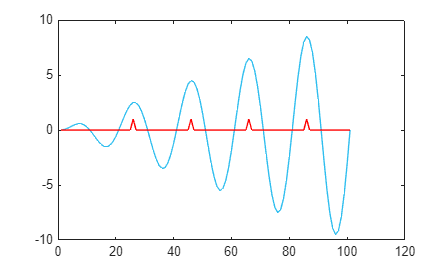

hold on 
plot(maximos,'r');

Si deseamos obtener los índices en los que se producen los máximos podemos hacerlo como:

find(maximos)

ans =     26    46    66    86


Como siempre en procesamiento de señal se debe prestar especial cuidado al funcionamiento en los bordes. El máximo final, en la muestra 102 probablemente no se deseaba detectarlo.